# Transfer Learning with A Deep Neural Network

% Set these to true if you want to actually perform the training and
% testing. Otherwise, we will use precomputed results.

warning on images:initSize:adjustingMag
warning on images:imshow:magnificationMustBeFitForDockedFigure

## Load a pretrained network and inspect it

net = googlenet;
layers = net.Layers;

## Test it on an image

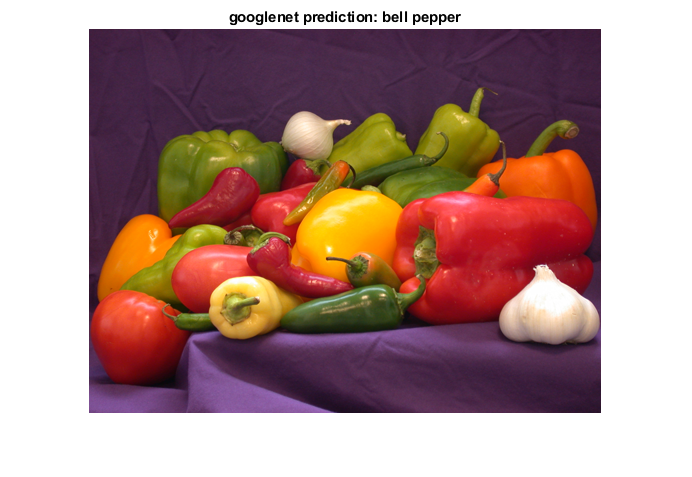

% img = imread('peppers.png');
% imgLabel = net.classify(imresize(img, [224 224]));
netName = 'googlenet';
% % display
% figure
% imshow(img)
% title([netName ' prediction: ' char(imgLabel)])

## Try it on another image

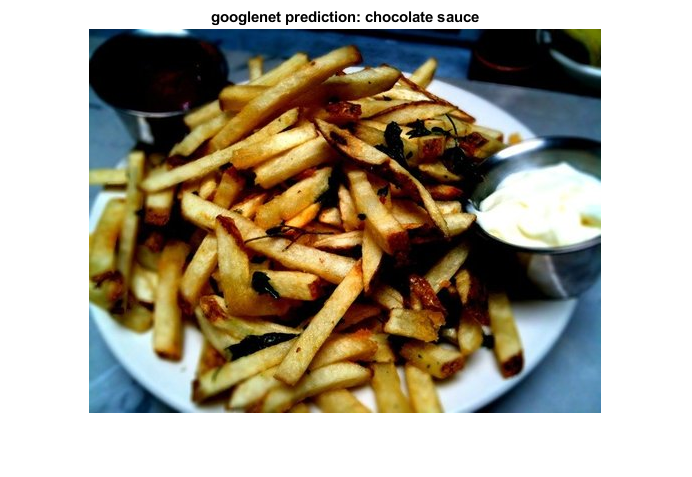

% img = imread('17394.jpg');
% imgLabel = net.classify(imresize(img, [224 224]));
% 
% % display
% figure
% imshow(img)
% title([netName ' prediction: ' char(imgLabel)])

## What were other top choices for classification?

The network also predicts other top choices for the class label of the object. You can use the "predict" method of the network to see other choices that were made.

prediction = predict(net,imresize(img, [224 224]));
[psorted, pind] = sort(prediction, 'descend');
numTopClasses = 3; % show top N choices
TopClasses = net.Layers(end).ClassNames(pind(1:numTopClasses));
Scores = psorted(1:numTopClasses)';
topTable = table(TopClasses, Scores) %#ok

topTable = 3×2 table
        TopClasses         Scores 
    ___________________    _______

    {'chocolate sauce'}    0.28587
    {'plate'          }    0.19347
    {'frying pan'     }    0.15759


## Load Image Data

Please note: the example in the ebook used data from the Food101 public dataset, available at [https://www.vision.ee.ethz.ch/datasets_extra/food-101/](https://www.vision.ee.ethz.ch/datasets_extra/food-101/) You can download the dataset and extract the following categories from the archive: - caesar_salad - french_fries - hamburger - pizza - sushi Place them in the imgData/train directory.

% if you have done this, set this flag to false. The example will run with
% the food images. 
runCIFARdata = false; %#ok

## Alternative Image Data source (Recommended)

While we encourage you to use the dataset of food above, a convienient and smaller dataset is also available for quicker download

% This may take a few minutes to download and save the images.
% DownloadCIFAR10()
categories = {'car','motorcycle','pedestrian'};
imagepath = fullfile('./imgData/cifar10Train/',categories);
runCIFARdata = true;

Data is 3 different categories. How do we read in all of these images? Create an imageDataStore to read images. Label all images based on their foldernames and include all subfolders in the directory Load in input images

if runCIFARdata
    imds = imageDatastore(imagepath,...
    'LabelSource','FolderNames');
else 
    imagepath = fullfile('imgData', 'train'); %#ok
    imds = imageDatastore(imagepath, 'IncludeSubfolders',true,...
        'LabelSource','FolderNames');
end
% display # of labels and count of each
imds.countEachLabel

ans = 3×2 table
      Label       Count
    __________    _____

    Car           1000 
    Motorcycle    1000 
    Pedestrian    1000 


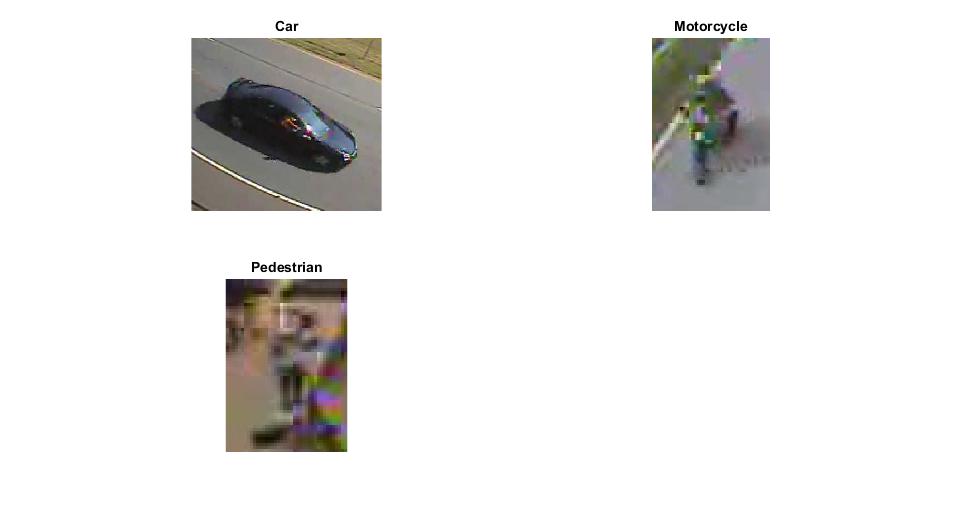

label_class = unique(imds.Labels);
nl = length(label_class);

% We can visually inspect individual images
visImds = splitEachLabel(imds,1,'randomize');
figure('name','visualize each label','NumberTitle','off');
set(gcf,'Position',[317  279  964  508])

for ii = 1:nl
    
    subplot(2,ceil(nl/2),ii);
    imshow(visImds.readimage(ii));
    title(char(visImds.Labels(ii)),'interpreter', 'none');
    
end

## Set an output function

Input images may have sizes that are different from the pre-trained network, so we want to preprocess images, resize them to be consistent with pre-trained networks.

imagesize = layers(1).InputSize;
outputSize = imagesize(1:2);
imds.ReadFcn = @(loc)imresize(imread(loc),outputSize);

## Alter network to fit our desired output.

We can clearly see that, without further training, the pretrained network does not do a good job predicting most of the new images. This is where transfer learning will shine and help improve prediction accuracy. 

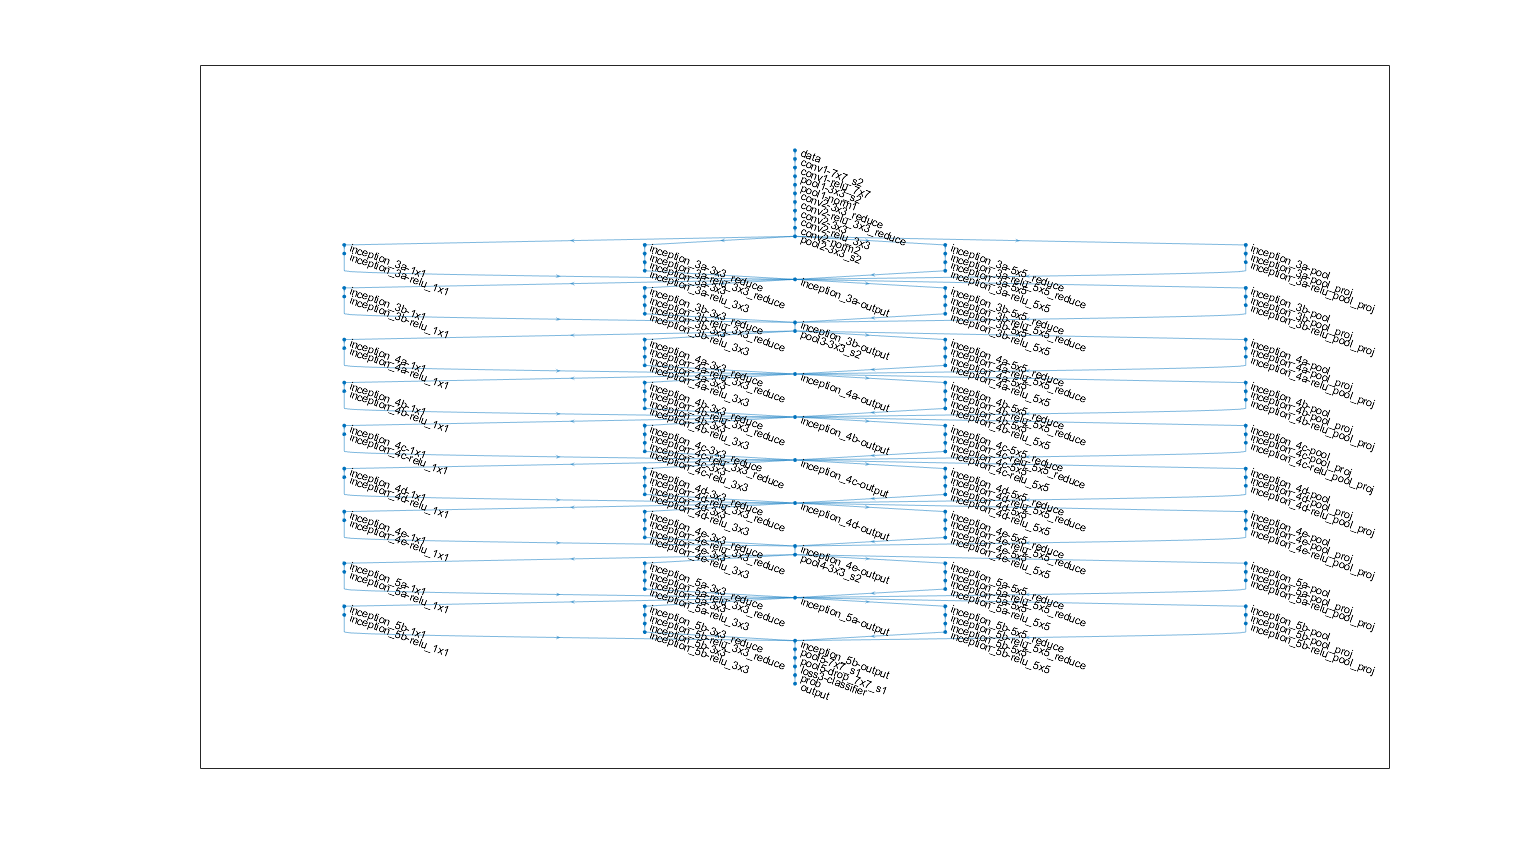

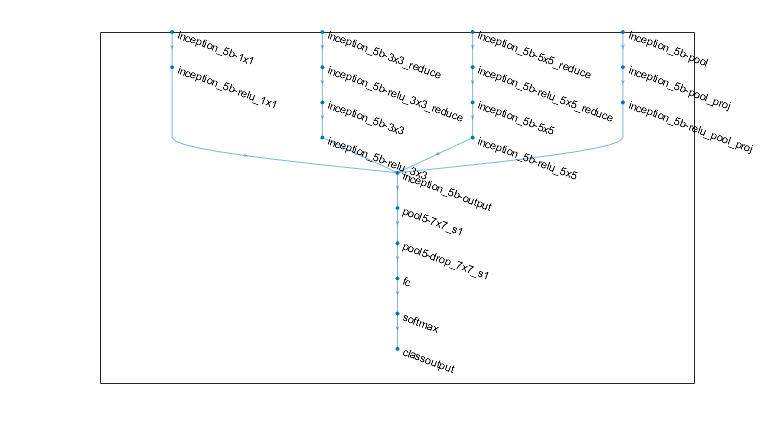

% Before we start training, let's partition the data into different sets.
% We will use 60% of images per category to train, 20% for validation, and
% specify 20% as a test set to test our network after it has been trained.
% We want to see how accurate our network is on data it has never seen before.

[trainDS,valDS] = splitEachLabel(imds,0.7,0.3, 'randomized');

% Note: operations will be different for series vs. DAG networks.
switch netName
    case {'alexnet','vgg16','vgg19'} % series network
        %
        % The pre-trained layers at the end of the network are designed to classify
        % 1000 objects. But we need to classify different objects now. So the
        % first step in transfer learning is to replace alter just two of the layers of the
        % pre-trained network with a set of layers that can classify 5 classes.
        %
        % Get the layers from the network. The layers define the network
        % architecture and contain the learned weights. Here we only alter two of
        % the layers. Everything else stays the same.
        
        num_objects = height(trainDS.countEachLabel);
        
        layers(end-2) = fullyConnectedLayer(num_objects, 'Name','fc8');
        layers(end) = classificationLayer('Name','classoutput');
        
        layers_train = layers;
        
    case 'googlenet' % DAG network
        % Extract the layer graph from the trained network and plot the layer
        % graph.
        lgraph = layerGraph(net);
        figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
        plot(lgraph)
        
        %
        % To retrain GoogLeNet to classify new images, replace the last three
        % layers of the network. These three layers of the network, with the names
        % |'loss3-classifier'|, |'prob'|, and |'output'|, contain the information
        % of how to combine the features that the network extracts into class
        % probabilities and labels. Add three new layers, a fully connected layer,
        % a softmax layer, and a classification output layer, to the layer graph.
        % Set the final fully connected layer to have the same size as the number
        % of classes in the new data set (5, in this example). To learn faster in
        % the new layers than in the transferred layers, increase the learning rate
        % factors of the fully connected layer.
        lgraph = removeLayers(lgraph, {'loss3-classifier','prob','output'});
        
        numClasses = numel(unique(categories(trainDS.Labels)));
        newLayers = [
            fullyConnectedLayer(numClasses,'Name','fc','WeightLearnRateFactor',20,'BiasLearnRateFactor', 20)
            softmaxLayer('Name','softmax')
            classificationLayer('Name','classoutput')];
        lgraph = addLayers(lgraph,newLayers);
        
        
        %
        % Connect the last of the transferred layers remaining in the network
        % (|'pool5-drop_7x7_s1'|) to the new layers. To check that the new layers
        % are correctly connected, plot the new layer graph and zoom in on the last
        % layers of the network.
        lgraph = connectLayers(lgraph,'pool5-drop_7x7_s1','fc');
        figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
        plot(lgraph)
        ylim([0,10])
        
        layers_train = lgraph;
end

## Start training

    opts = trainingOptions('sgdm','InitialLearnRate',0.001,...
        'ValidationData',valDS,...
        'Plots','training-progress',...
        'MiniBatchSize', 10,...
        'ValidationPatience', 3);
    % If you get an out of memory error for thde GPU, please lower the
    % 'MiniBatchSize' to a lower value.

    % Training with the optimized set of hyperparameters
    tic
    disp("Initialization may take up to a minute before training begins")

Initialization may take up to a minute before training begins


Training on single GPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:26 |       30.00% |       34.78% |       2.0246 |       5.5225 |          0.0010 |


|       1 |          50 |       00:02:14 |       60.00% |       81.67% |       0.6744 |       0.4792 |          0.0010 |


|       1 |         100 |       00:04:02 |       70.00% |       84.00% |       1.0317 |       0.4373 |          0.0010 |


|       1 |         150 |       00:05:52 |       80.00% |       87.56% |       0.6176 |       0.3202 |          0.0010 |


|       1 |         200 |       00:07:35 |      100.00% |       91.22% |       0.2131 |       0.2746 |          0.0010 |


|       2 |         250 |       00:09:20 |       80.00% |       92.44% |       0.3929 |       0.2394 |          0.0010 |


|       2 |         300 |       00:11:16 |       80.00% |       89.44% |       0.6012 |       0.3352 |          0.0010 |


|       2 |         350 |       00:13:05 |      100.00% |       90.22% |       0.0350 |       0.2763 |          0.0010 |


|       2 |         400 |       00:14:48 |      100.00% |       90.89% |       0.0485 |       0.2322 |          0.0010 |


|       3 |         450 |       00:16:35 |      100.00% |       94.78% |       0.0212 |       0.1471 |          0.0010 |


|       3 |         500 |       00:18:31 |       90.00% |       94.33% |       0.1301 |       0.1904 |          0.0010 |


|       3 |         550 |       00:20:21 |       80.00% |       95.00% |       0.3073 |       0.1620 |          0.0010 |


|       3 |         600 |       00:22:03 |      100.00% |       93.56% |       0.0958 |       0.1844 |          0.0010 |


|======================================================================================================================|


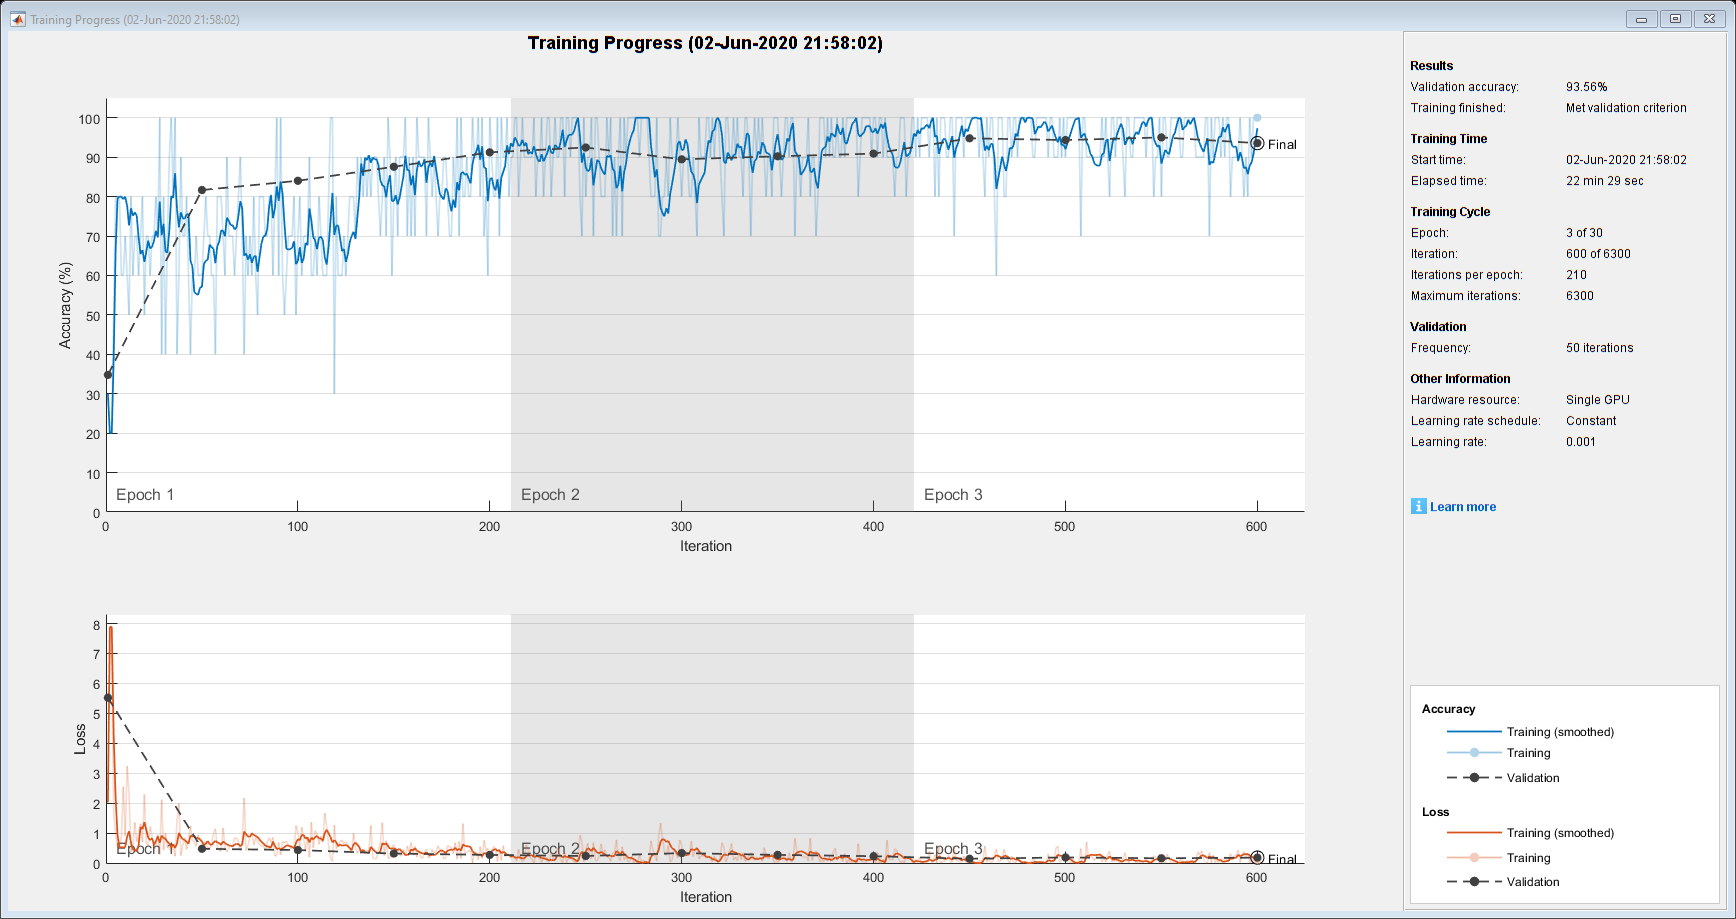

    net = trainNetwork(trainDS, layers_train, opts);

    toc

Elapsed time is 1365.744655 seconds.


## Test new classifier on validation set

Now run the network on the test data set to see how well it does Please note: this will take a while to run.

% imgTest = imread('testCar2.jpg');
% imgLabel = net.classify(imresize(imgTest, [224 224]));
% 
% % display
% figure
% imshow(imgTest)
% title([netName ' prediction: ' char(imgLabel)])

v = VideoReader("AIVideo.mp4");

numberOfFramesInspected = [100, 120, 180, 250]

numberOfFramesInspected =    100   120   180   250


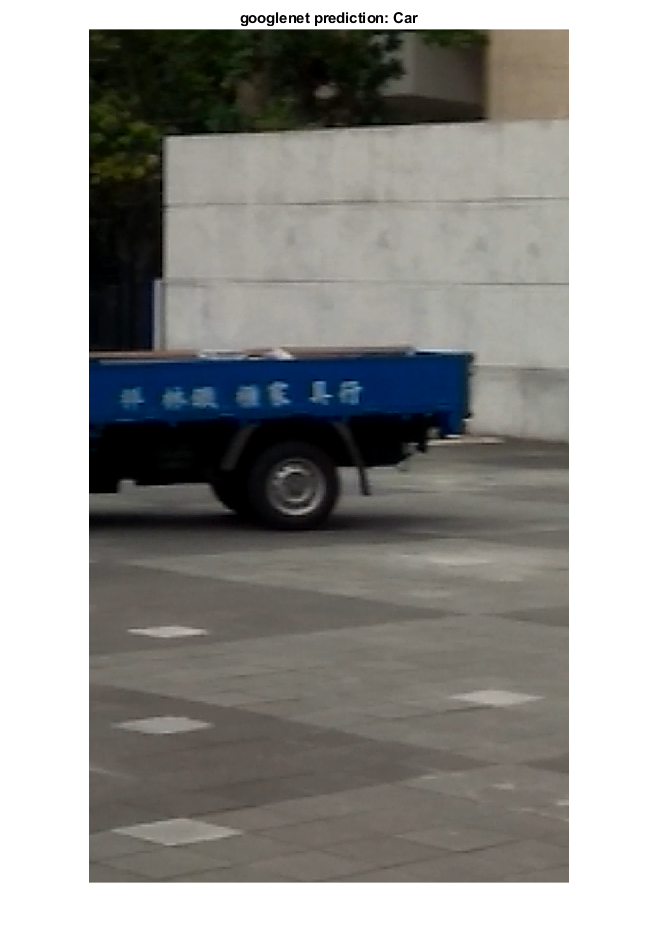

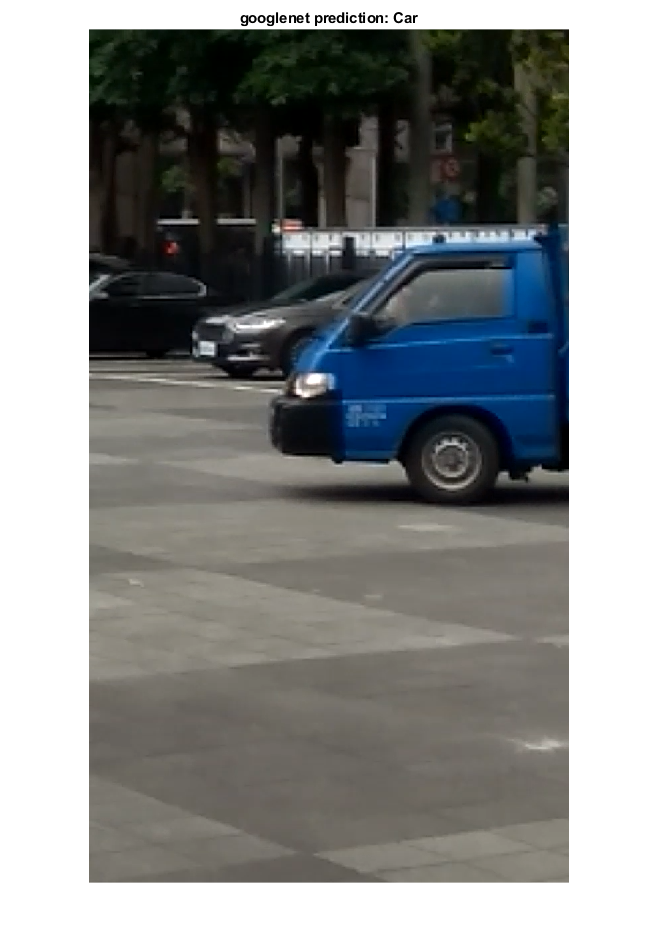

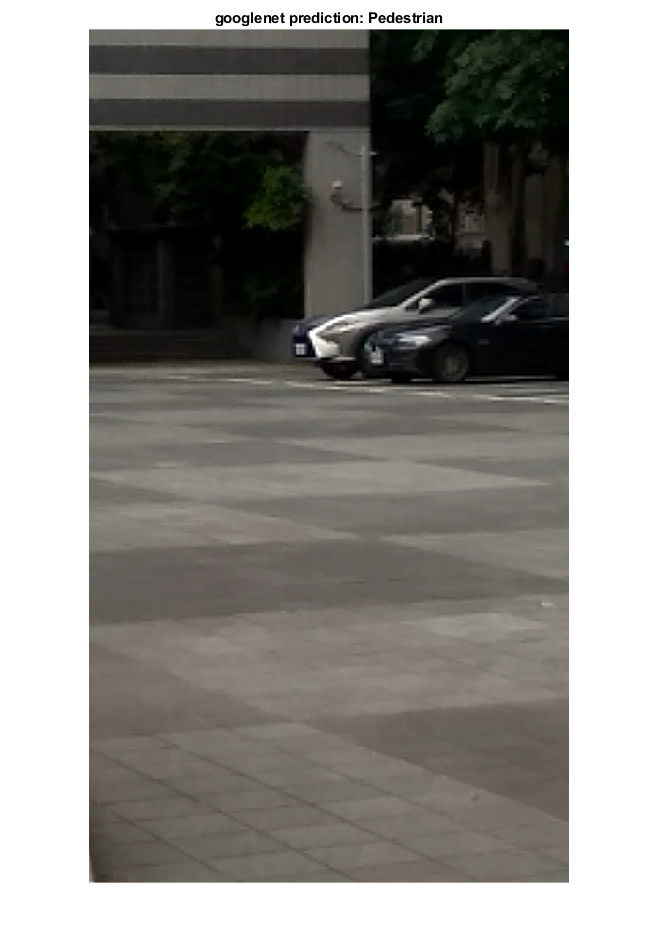

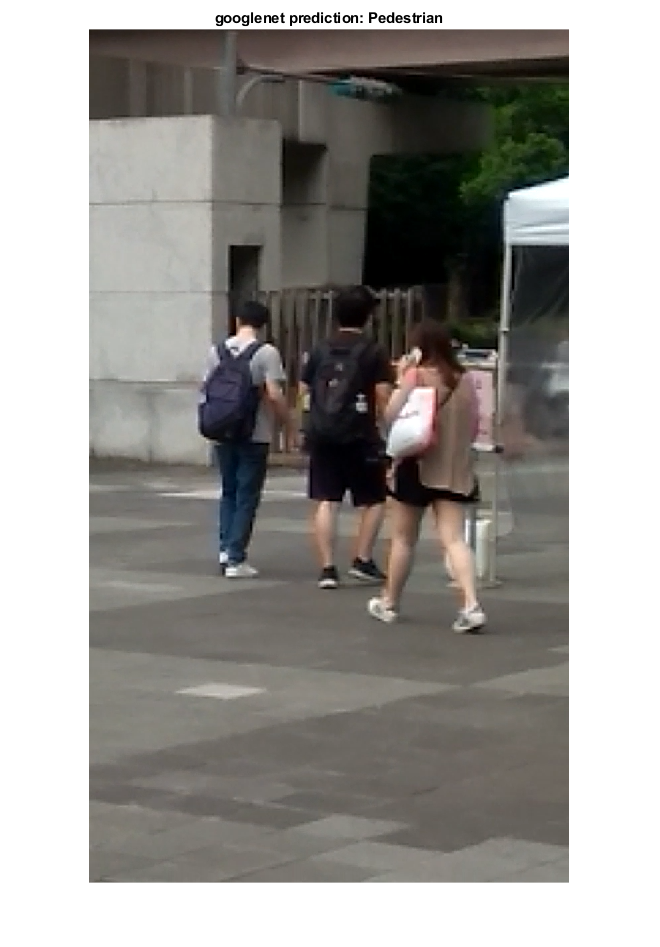


for i = 1 : length(numberOfFramesInspected)
    frame = read(v,numberOfFramesInspected(i));
    imgLabel = net.classify(imresize(frame, [224 224]));    
    figure
    imshow(frame)
    title([netName ' prediction: ' char(imgLabel)])
%     imshow(frame)
    
end    

    
    
% if runCIFARdata
%     testDS = imageDatastore(fullfile('imgData/cifar10Test',categories),...
%     'LabelSource','FolderNames');
% else
%     imagepath = fullfile('imgData', 'test');  %#ok
%     testDS = imageDatastore(imagepath, 'IncludeSubfolders',true,...
%     'LabelSource','FolderNames');
% end
% 
% testDS.ReadFcn = imds.ReadFcn;
% 
% tic
% [labels,err_test] = classify(net, testDS, 'MiniBatchSize', 128);
% toc
% 
% accuracy_default = sum(labels == testDS.Labels)/numel(labels);
% disp(['Test accuracy is ' num2str(accuracy_default)])
% 
% % Somewhat easy confusion matrix - heat map (Base MATLAB - new in 17A)
% tt = table(labels, testDS.Labels,'VariableNames',{'Predicted','Actual'});
% figure('name','confusion matrix'); heatmap(tt,'Actual','Predicted');
% pause(1)
% 
% % Or create a more 'sophisticated' confusion matrix
% tbl = testDS.countEachLabel;
% t = zeros(nl,length(labels));
% y = t;
% for ii = 1:nl
%     y(ii,:) = labels == tbl.Label(ii);
%     t(ii,:) = testDS.Labels == tbl.Label(ii);
% end
% figure;
% plotconfusion(t,y);

## Choose a random image, visualize the results and show the confidence

% randNum    = randi(length(testDS.Files));
% im_display = imread(testDS.Files{randNum});
% actualLabe = testDS.Labels(randNum);
% im         = imresize(im_display,outputSize);
% 
% [label,conf] = classify(net,im); % classify with deep learning
% imshow(im_display);
% title(sprintf('%s %.2f, actual %s', char(label),max(conf),char(actualLabe)),'interpreter', 'none');

## (optional) Fine-tune with Bayesian optimization

%     disp('Fine-tune the network with Bayesian Optimization')
%     optVars = [
%          optimizableVariable('Momentum',[0.8 0.95])
%         optimizableVariable('InitialLearnRate',[1e-4, 10e-2],'Transform','log')
%         % optimizableVariable('LearnRateDropFactor',[40e-2, 99e-2],'Transform','log')
%         % optimizableVariable('LearnRateDropPeriod',[5, 45],'Type','integer')
%         % optimizableVariable('MaxEpochs',[50, 500],'Type','integer')
%         % optimizableVariable('MiniBatchSize',[ceil(0.005*size(trainDS.Labels,1)),ceil(0.05*size(trainDS.Labels,1))],'Type','integer')
%         % optimizableVariable('L2Regularization',[1e-10 1e-2],'Transform','log')
%         ];
%     
%     %
%     ObjFcn = BayesOpt_cnn(trainDS,valDS,netName);
%     
%     tic; % Time Start
%     BayesObject = bayesopt(ObjFcn,optVars,...
%         'MaxObj',15,...
%         'MaxTime',60*60,...
%         'IsObjectiveDeterministic',false,...
%         'UseParallel',false); % set UseParallel as true for faster results.
%     toc; % Time End

## Assess best points according to Bayesian Optimization

You can decide whether to fine tune the model again (based on optimization results), or simply use the set of hyperparameters for training.

%     % Here we will proceed with the set of best points, returned by:
%     opts_param = BayesObject.bestPoint;
%     
%     % Define training options
%     opts_best = trainingOptions('sgdm','InitialLearnRate',opts_param.InitialLearnRate,...
%             'ValidationData',valDS,...
%             'Plots','training-progress',...
%             'MiniBatchSize', 64,...
%             'ValidationPatience', 3);
%     
%     % Training with the optimized set of hyperparameters
%     tic
%     disp("Initialization may take up to a minute before training begins")
%     net = trainNetwork(trainDS, layers_train, opts_best);
%     toc
%     
%     % performance check
%     accuracy_bayesopt = validatePerformance(net,testDS) %#ok display

*Copyright 2018 The MathWorks, Inc.*